# **Interpolazione e Smoothing : Fitting di Dati**

## Questo documento mira ad illustare esempi d'utilizzo significativi per problemi di interpolazione e smoothing utilizzando le funzioni Matlab.

# **Interpolazione e Smoothing : Fitting di Dati**

## Questo documento mira ad illustare esempi d'utilizzo significativi per problemi di interpolazione e smoothing utilizzando le funzioni Matlab.

# Interpolazione

## **Tool di interpolazione**

Nella seguente sezione viene presentato un tool nel quale esplicitando il numero di punti sul grafico viene mostrato il confronto tra le varie tipologie di interpolazione messe a disposizione dal MATLAB. Si può scegliere il tipo di interpolazione desiderato tramite menù a tendina**.**

**Per eseguire il tool, basta digitare nella Command Line del MATLAB : *****"GUI_Interpol"***

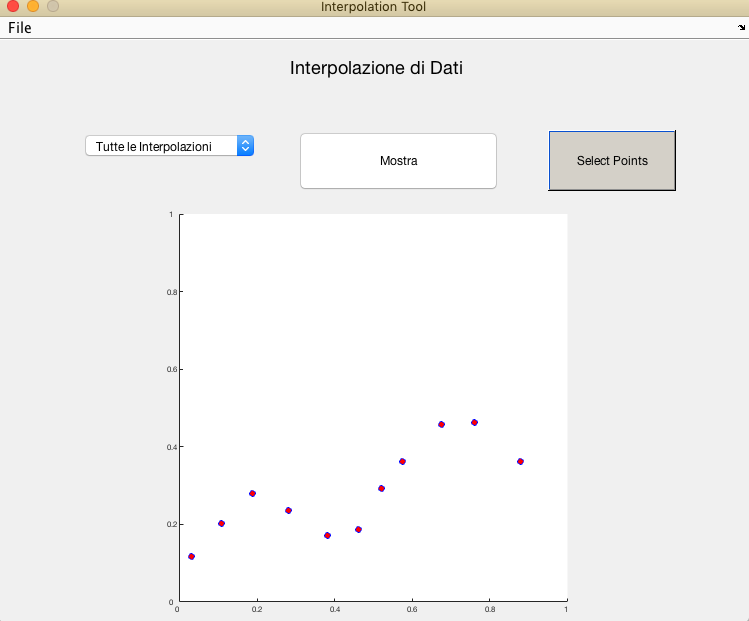

Da come si nota dalla figura in sovraimpressione, il tool presenta i seguenti componenti:

- Pulsante di selezione dei punti

- Pulsante di esecuzione del metodo di interpolazione (Mostra)

- Menù a tendina della scelta del metodo

- Assi coordinati

Cliccando sul pulsante di selezione dei punti è possibile:

- Selezionare con il tasto sx del mouse il numero di punti di coordinata x crescente (da sx verso dx)

- Prima di completare la selezione specificare con il tasto dx del mouse l'ultimo punto di coordinata x più grande

Una volta effettuata la selezione dei punti, scegliere il metodo di interpolazione desiderato e cliccare sul pulsante "Mostra". Di seguito mostriamo alcuni esempi del tool:

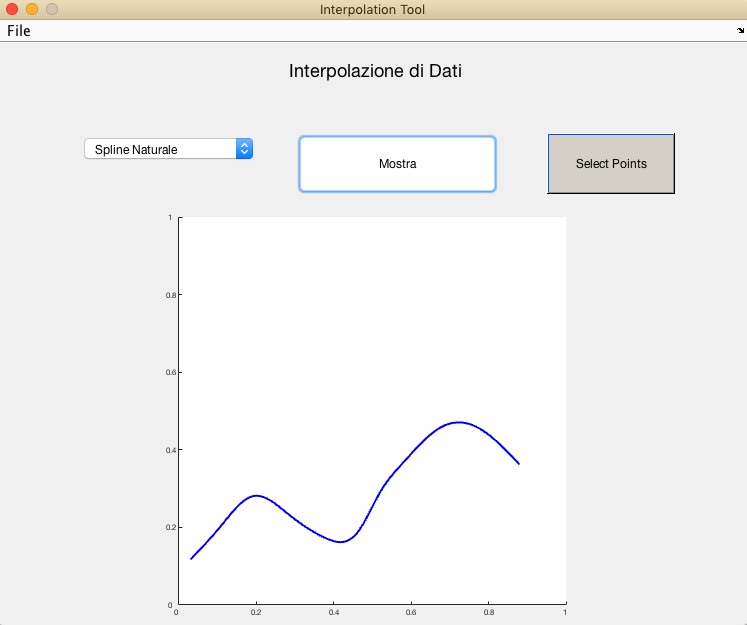

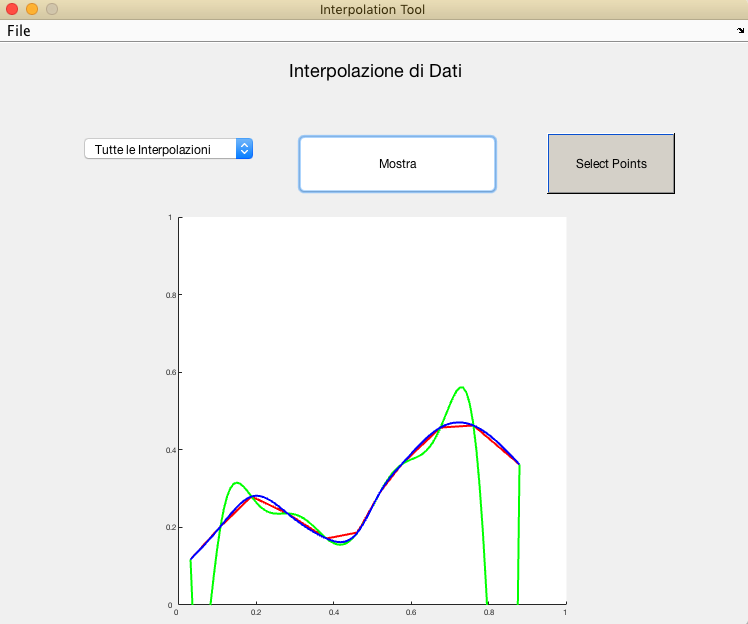

Dall'ultima immagine possiamo notare che il metodo Polinomiale (rappresentato dalla curva in verde) è meno accurato data la sua natura oscillante. Per questo, si preferisce in tante applicazioni, usare il metodo Spline (rappresentato dalla curva in blu).

## Esempi di applicazione dei metodi di interpolazione

Viene preso in considerazione un dataset contenente dati annuali dal 1922 al 1999 sui `Rendimenti Azionari Danesi` escludendo rendimenti non specificati (indicati come NaN). Da queste informazioni viene ricavato un andamento preciso attraverso i metodi di interpolazione.

**Il seguente codice mostra l'andamento del valore di rendimento annuo "DY"**

load Data_Danish.mat
%Esclusione dati non specificati
rvi = find(~isnan(Data(:,1)));
anno = dates(rvi);
rendita_anno = Data(rvi,1);


**Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di interpolazione polinomiale **

periodo = 1922:0.1:1999;
p=polyfit(anno,rendita_anno,length(rendita_anno)-1);  %pol.int.  grado 5

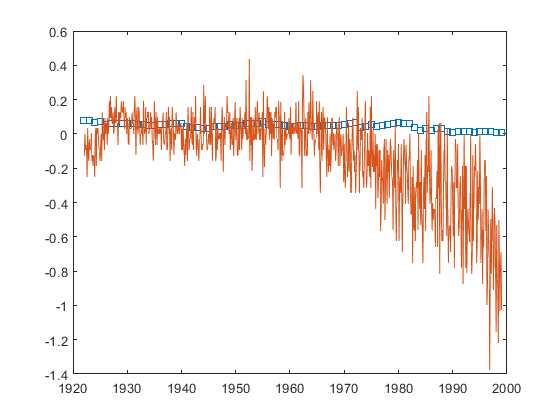

f=polyval(p,periodo);
plot(anno,rendita_anno,'s',periodo,f)

Si nota che il polinomio interpolante  non è un buon modello per descrivere il fenomeno che ha originato i dati.Infatti i polinomi di grado elevato oscillano fortemente tra i dati. Matlab per avvertire l'utente di questa condizione genera un warning se usiamo polinomi di grado maggiore di 10.

Poichè l'uso dei polinomi è facilmente gestibile via software , ma la funzione interpolante ha uno stretto legame tra grado e numero di nodi si utilizza la tecnica dell'interpolazione a tratti.

**Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di interpolazione polinomiale a tratti**

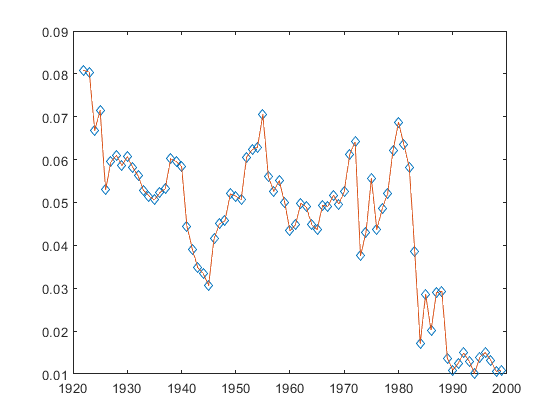

pt=interp1(anno,rendita_anno,periodo);
plot(anno,rendita_anno,'d',periodo,pt)

Questo modello è efficiente ed accurato, inoltre ha una convergenza migliore rispetto all'interpolazione polinomiale, infatti più nodi prendo meglio si approssima il modello. Però il problema di questo modello è che la funziona ha punti spigolosi, ma a noi interessa avere una curva liscia e senza spigoli.

**Mostriamo l'andamento del rendimento annuo con l'utilizzo del metodo di Spline. **

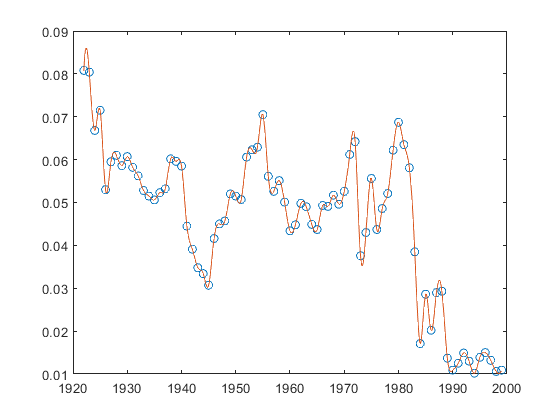

sp = spline(anno,rendita_anno);
periodo = 1922:0.1:1999;
%La funzione ppval restituisce un grafico a partire dai valori restituiti da spline
graf = ppval(sp,periodo);
plot(anno,rendita_anno,'o',periodo,graf)

Come si nota dal grafico, la curva è diventata liscia e senza spigoli.

Analizzando il problema trattato da questo modello si nota che  il rendimento annuale danese è diminuito vertiginosamente dagli inizi degli anni 80 fino alla prima metà, questo calo drastico si è propagato anche negli anni successivi.

**Si mostra l'andamento utilizzando un metodo di interpolazione Spline Cubica Naturale.**

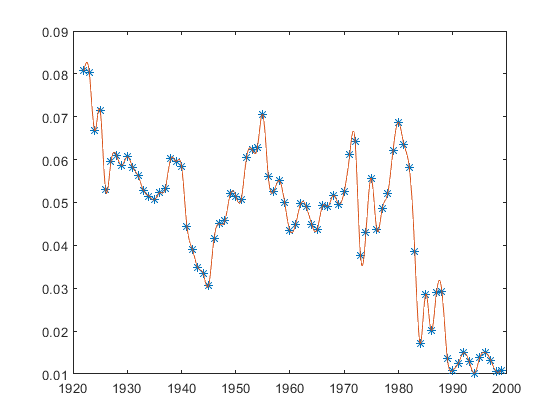

sp = csape(anno,rendita_anno,'second');
graf = ppval(sp,periodo);
plot(anno,rendita_anno,'*',periodo,graf)

## Interpolazione Spline e utilizzo della Derivata

**In questa sezione si mostrano degli esempi sulla Spline Interpolante e come questa permette di rappresentare la derivata di una funzione.**

Il codice seguente mostra le differenze tra la funzione, la rappresentazione Spline Not-A-Knot e Cubica Naturale**. **

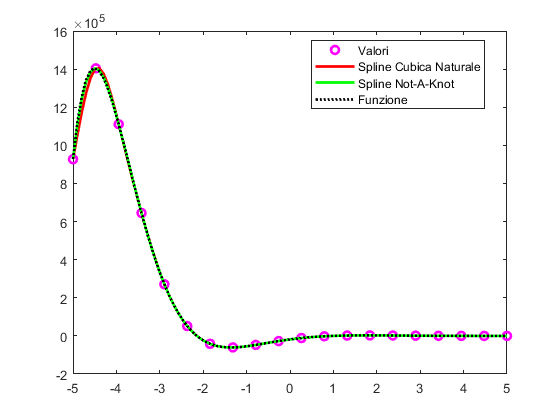

x1 = linspace(-5,5,20); %Asse x su 20 punti
x2 = linspace(-5,5,100); %Asse x su 100 punti
% Funzione
fx1 = exp(-x1 + 10).*cos(x1 + 10);
fx2 = exp(-x2 + 10).*cos(x2 + 10);
% Rappresentazione Spline Not-A-Knot
pp1 = spline(x1,fx1);
sp1 = ppval(pp1,x2);
% Rappresentazione Spline Cubica Naturale
pp2 = csape(x1,fx1,'second');
sp2 = ppval(pp2,x2);
plot(x1,fx1,'om',x2,sp2,'r',x2,sp1,'g',x2,fx2,':k','LineWidth',2);
legend('Valori','Spline Cubica Naturale','Spline Not-A-Knot','Funzione','Location',"best");

Da come si può notare la Spline Not-A-Knot risulta molto più accurata rispetto alla Cubica Naturale.

**Si confronta la derivata analitica della funzione con la sua rappresentazione Spline ottenuta tramite la funzione "fnder".**

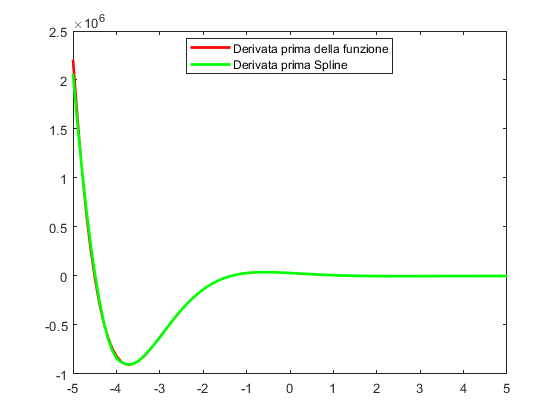

% Utilizzo della derivata
y_primo = -exp(-x2+10).*(sin(x2+10)+cos(x2+10));
sp_derivata = fnder(pp1,1);
pp3 = ppval(sp_derivata,x2);
plot(x2,y_primo,'r',x2,pp3,'g','LineWidth',2);
legend('Derivata prima della funzione','Derivata prima Spline','Location','best');

Un ulteriore conferma la otteniamo con la derivata, fnder risulta molto più accurata rispetto alla derivata analiticamente calcolata.

# Interpolazione bidimensionale e Smoothing di dati

## **Interpolazione di curve parametriche**

Fino a questo momento abbiamo visto come le tecniche di interpolazione polinomiale permettano di valutare l’andamento di funzioni nelle quali i punti sono posti in serie. Se la funzione da interpolare è parametrica e l ’insieme dei suoi punti disegna  nello spazio delle curve chiuse, non è possibile sfruttare direttamente i metodi fin qui analizzati, si userà la spline interpolante parametrica.

Interpolazione della spirale

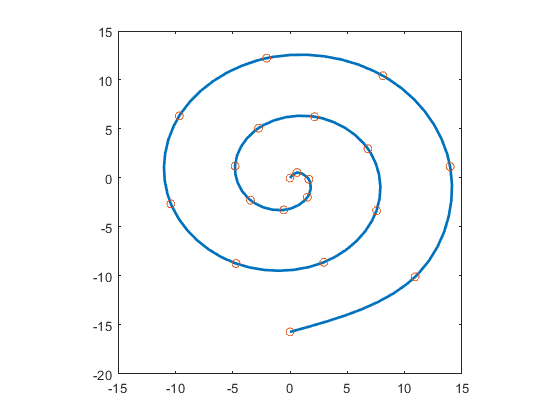

%interpolazione spirale
t=linspace(0,5*pi,20);
x =t.*sin(t);y =t.*cos(t);
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
axis square

figure

Si mostra l'interpolazione del cardioide

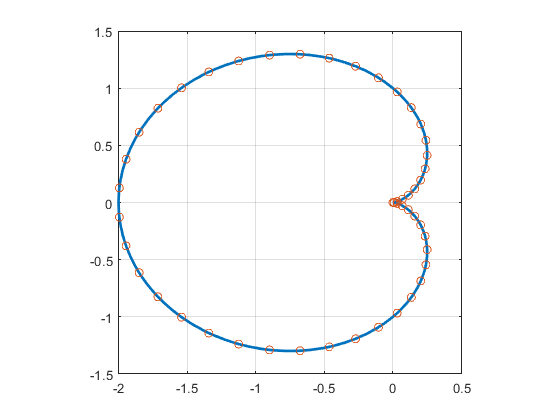

%Cardiode
t=linspace(0,2*pi,50);
x=cos(t).*(1-cos(t)); y=sin(t).*(1-cos(t));
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
grid on
axis square

figure

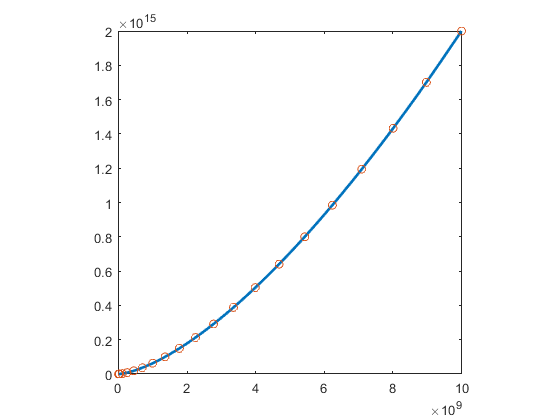

%interpolazione folium di cartesio
t=linspace(0,100000,20);
x =t.*sin(t);y =t.*cos(t);
x=t.*(t-1) ; y = t.*(t - 1).*(2*t - 1);
points=[x;y];
fnplt(cscvn(points)); hold on,
plot(points(1,:),points(2,:),'o')
axis square

## Estrapolazione e Previsione dei Dati

Il Matlab mette a disposizione una particolare funzione "fnxtr" che consente di prevedere il comportamento di alcune funzioni. In alcuni casi, in abbinata all'Interpolazione Spline consente di dare una rappresentazione di una funzione quasi uguale al caso reale.

In questa sezione, testiamo il comportamento della funzione degli errori "erf" attraverso l'utilizzo del comando "fnxtr" e confrontiamo il risultato con una rappresentazione attraverso un polinomio di secondo grado.

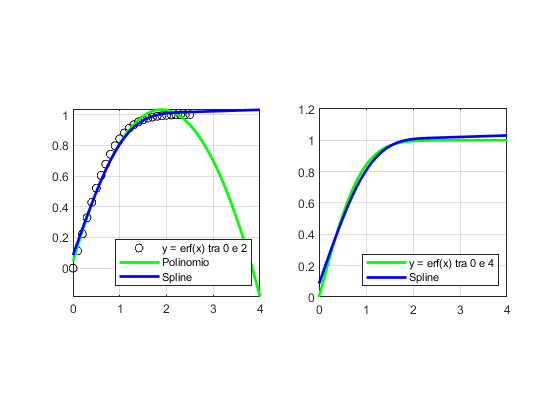

clear
x = 0:0.1:2.5;
y = erf(x); % Funzione Errore tra 0 e 2
% Utilizzo della funzione fnxtr in abbinata alla Spline Cubica Naturale
result = fnxtr(csaps(x,y,.85));
poli = polyfit(x,y,2);
x1 = 0:0.1:4;
f = polyval(poli,x1); %Polinomio di secondo grado
ys = ppval(result,x1); %Spline Cubica Naturale + fnxtr
y1 = erf(x1); % Funzione Errore tra 0 e 4
subplot(1,2,1)
primo = plot(x,y,'ko',x1,f,'g',x1,ys,'b'); 
grid
legend('y = erf(x) tra 0 e 2','Polinomio','Spline','Location','southeast')
axis square
subplot(1,2,2)
secondo = plot(x1,y1,'g',x1,ys,'b');
grid
legend('y = erf(x) tra 0 e 4','Spline','Location','southeast')
axis square
primo(2).LineWidth = 2;
primo(3).LineWidth = 2;
secondo(1).LineWidth = 2;
secondo(2).LineWidth = 2;

Da come si può notare, nel primo grafico il comportamento del polinomio perde non appena si supera il valore per x uguale a 1 mentre la Spline rimane sulla condizione di asintoticità della funzione. Nel secondo caso il comportamento della Spline differisce leggermente dal valore della funzione stessa.

**Andando a calcolare la differenza tra la funzione erf e la spline e la funzione erf con il polinomio si nota come il residuo è strettamente differente nei due casi.**

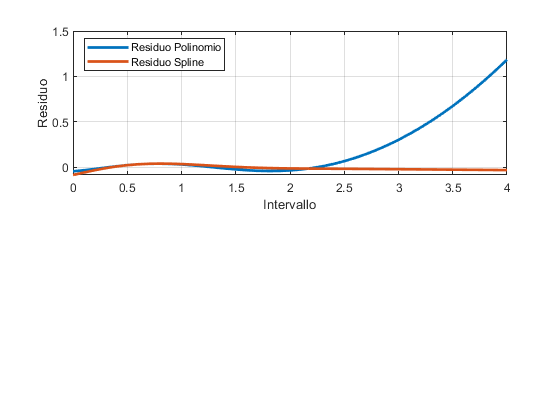

resid_polinomio = y1 - f;
resid_spline = y1 - ys;
vettore = [resid_polinomio' resid_spline'];
subplot(2,1,1)
p = plot(x1,vettore);
xlabel('Intervallo')
ylabel('Residuo')
legend('Residuo Polinomio','Residuo Spline','Location','northwest')
grid;
p(1).LineWidth = 2;
p(2).LineWidth = 2;

## Interpolazione di Curve Bidimensionali

L'impiego dei metodi di interpolazione risulta molto efficiente quando si devono adoperare funzioni e oggetti in più dimensioni. Di seguito mostriamo alcuni esempi sull'utilizzo dell'interpolazione Spline su curve bidimensionali.

## **Paraboloide Ellittico**

**Un primo esempio di superfice è il Paraboloide Ellittico, nel codice di seguito ne troviamo una parametrizzazione.**

u = -1:0.1:1;
v = -1:0.1:1;
[u,v] = meshgrid(u,v);
x = 5.*cosh(u).*cosh(v);
y = 5.*cosh(u).*sinh(v);
z = 3.*sinh(u);

**Generando il grafico in tre dimensioni della superfice si ottiene una rappresentazione non regolare**

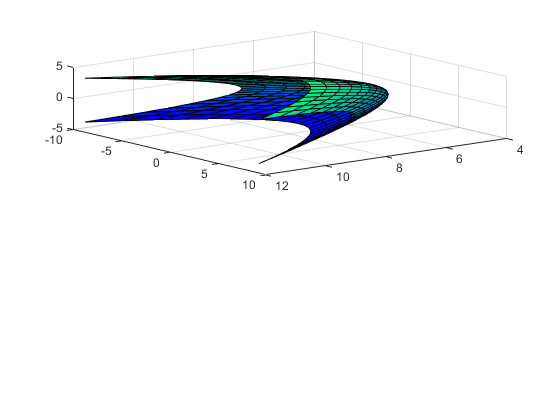

surf(x,y,z)
colormap winter
view([20,25,30])

**Utilizzando dunque un interpolazione Spline su 3 dimensioni si riesce ad avere una superfice più liscia e precisa.**

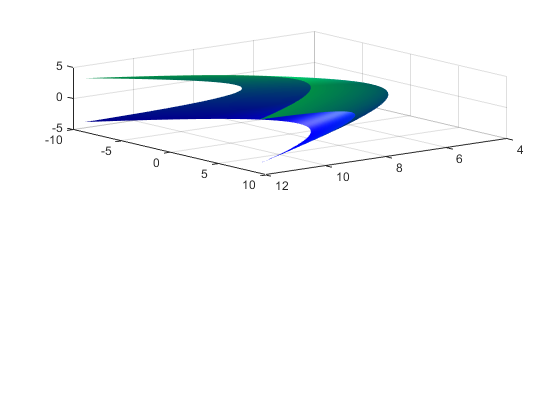

[u1,v1] = meshgrid(-1:0.01:1,-1:0.01:1);
x2 = interp2(u,v,x,u1,v1,'spline');
y2 = interp2(u,v,y,u1,v1,'spline');
z2 = interp2(u,v,z,u1,v1,'spline');
surfl(x2,y2,z2,'light')
colormap winter
shading interp
view([20,25,30])

# Smoothing

In questa sezione, saranno presentate le funzionalità del Matlab relative allo Smoothing di Dati. In particolare focalizzandoci su determinati risultati, verranno mostrati alcuni esempi nei quali le tecniche di interpolazione risultano utili nel prevedere situazioni che accadranno nel futuro. Infine descriviamo come queste tecniche sono adoperate nel miglioramento delle immagini e come i software ne fanno ampiamente uso.

## **Miglior Squadra di Calcio in Termini di Reti fatte**

L'esempio sopra intitolato riporta una rappresentazione grafica del numero reti fatte ad oggi differite per Team. Per questo aspetto viene fatta una previsione sul team che segnerà il maggior numero di reti nel successivo campionato utilizzando una tecnica di interpolazione lineare a tratti. Infine viene effettuato un confronto tra le varie tecniche di interpolazione mostrando come la tecnica di interpolazione Spline risulta la migliore anche nel caso dello Smoothing di Dati.

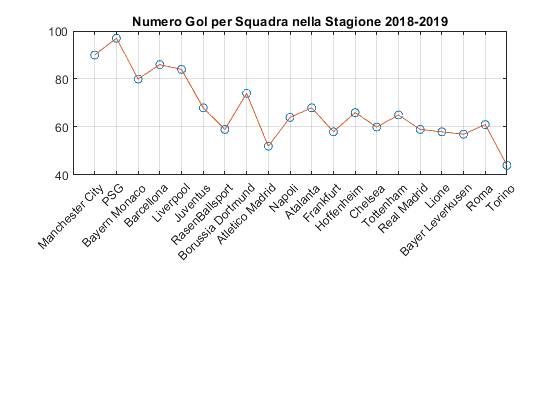

%Definisco il vettore di valori
x = 1:20;
gol = [90 97 80 86 84 68 59 74 52 64 68 58 66 60 65 59 58 57 61 44];
% Asse dei tempi
t = 1:0.1:20; %numero squadre
% Interpolazione Lineare a Tratti
z = interp1(x,gol,t);
plot(x,gol,'o',t,z)
xticks(x);
xticklabels({'Manchester City','PSG','Bayern Monaco','Barcellona','Liverpool','Juventus','RasenBallsport','Borussia Dortmund','Atletico Madrid','Napoli','Atalanta','Frankfurt','Hoffenheim','Chelsea','Tottenham','Real Madrid','Lione','Bayer Leverkusen','Roma','Torino'});
xtickangle(45);
title('Numero Gol per Squadra nella Stagione 2018-2019');
grid

**Vediamone ora il comportamento mettendo a confronto la rappresentazione attraverso un polinomio di 1 grado , 2 grado e la rappresentazione con il metodo interpolante Spline.**

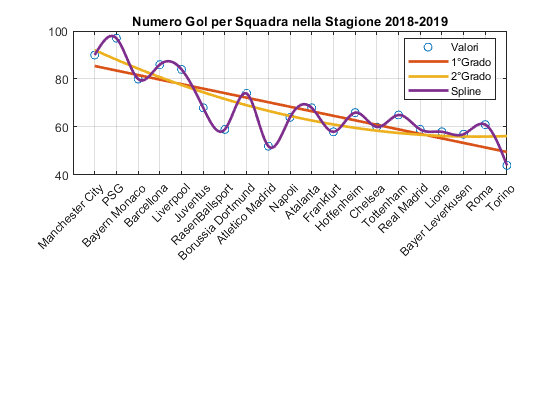

c1 = polyfit(x,gol,1);
c2 = polyfit(x,gol,2);
f1 = polyval(c1,t);
f2 = polyval(c2,t);
pp = csaps(x,gol,1);
ys1 = ppval(pp,t);
p = plot(x,gol,'o',t,f1,t,f2,t,ys1);
grid
legend('Valori','1°Grado','2°Grado','Spline')
p(4).LineWidth = 2; p(2).LineWidth = 2; p(3).LineWidth = 2;
xticks(x);
xticklabels({'Manchester City','PSG','Bayern Monaco','Barcellona','Liverpool','Juventus','RasenBallsport','Borussia Dortmund','Atletico Madrid','Napoli','Atalanta','Frankfurt','Hoffenheim','Chelsea','Tottenham','Real Madrid','Lione','Bayer Leverkusen','Roma','Torino'});
xtickangle(45);
title('Numero Gol per Squadra nella Stagione 2018-2019');

Ovviamente da come si può notare, il polinomio di 2°Grado non approssima minimamente l'andamento delle reti segnate dato che esso è malcondizionato. In contrapposizione, l'andamento Spline è l'ideale mostrando esattamente il possibile andamento dei valori.

## **Valutazione delle Performance dell'Algoritmo di Jacobi**

In questo esempio mostriamo come le tecniche di smoothing sono adatte per misurare le performance di un algoritmo. Stimando, al crescere del numero di esecuzioni dell'algoritmo, i tempi necessari per l'esecuzione mostrando l'errore dovuto al carico del calcolatore e alla gestione del sistema operativo che ne fa l'esecuzione.

**Il modello di interpolazione utilizzato è quello del polinomio di secondo grado dei minimi quadrati e l'algoritmo utilizzato è il metodo iterativo di Jacobi per la risoluzione di un sistema lineare.**

% Pulizia Workspace
clear all
% Definizione del Numero di esecuzioni e del Vettore dei tempi raccolti
N = 1000;
T = zeros(1,N);
%Chiamate all'algoritmo
for i=1:N
    A = sprand(i,i,0.03)+spdiags(ones(i,1),0,i,i)*3;
    b = rand(length(A),1);
    TOL = 10^-14;
    MAXITER = 800;
    tic;
    [res,~,~] = Jacobi(A,b,TOL,MAXITER);
    T(i) = toc;
end

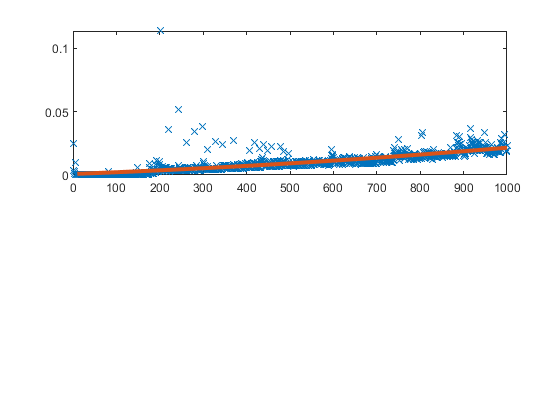

x = linspace(1,N,N);
coef = polyfit(x,T,2);
t = 10:0.001:N;
fx = polyval(coef,t);
p = plot(x,T,'x',t,fx);
p(2).LineWidth = 3;

Il polinomio mostra come l'andamento dei tempi di esecuzione dell'algoritmo cresce man mano che aumentano il numero di iterazioni effettuate. Tuttavia esso approssima in maniera pressocchè corretta sia l'errore di misurazione e sia la complessità computazionale dell'algoritmo.

## **Tool per lo Smoothing delle Immagini**

Come già anticipato, lo smoothing risulta molto utile quando si vuole migliorare la qualità di un immagine. E' stato realizzato un tool apposito che permette di caricare un immagine e di effettuare lo Smoothing mettendo a confronto il metodo interpolante Lineare con quello Spline assieme all'immagine originale. Inoltre e' possibile effettuare uno zoom immagine per ottenere una migliore visualizzazione dell'effetto prodotto tramite lo Smoothing.

Per eseguire il tool, bisogna digitare nella Command Line del MATLAB il comando "*GUI_Image_Smoothing"*

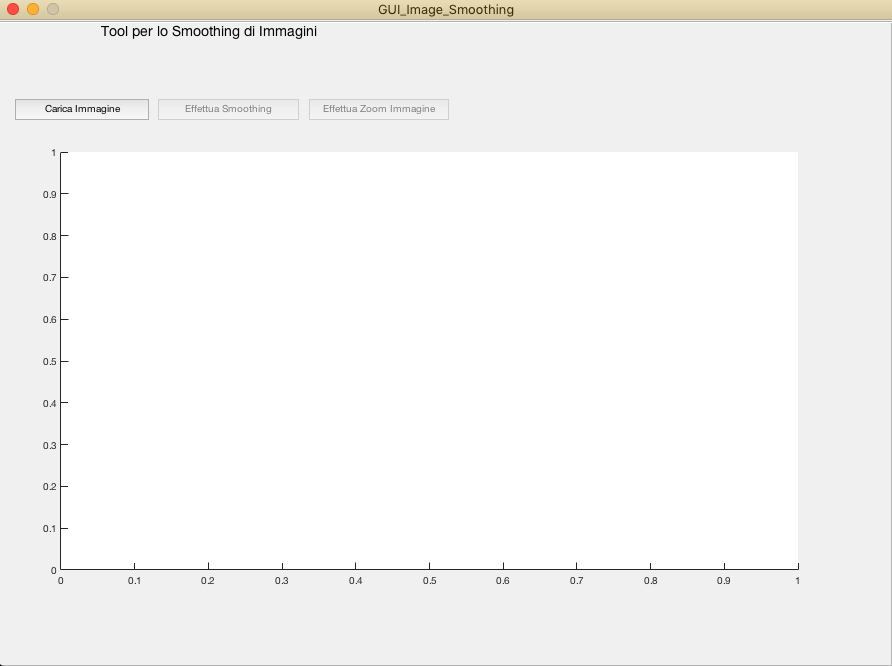

Il tool presenta:

- Un asse coordinato utilizzato per mostrare le immagini secondo la loro scala di pixel

- Un pulsante "Carica Immagine" che una volta cliccato permette di selezionare l'immagine in formato ".jpg .gif .png" e di conseguenza selezionata l'immagine abilita i pulsanti "Effettua Smoothing" e "Effettua Zoom Immagine"

- Il pulsante "Effettua Smoothing" che mostra le caratteristiche dello Smoothing

- Il pulsante "Effettua Zoom Immagine" che mostra le caratteristiche dello Smoothing ancora di più nel dettaglio

Di seguito mostriamo alcuni esempi di utilizzo del tool.

- Click su "Carica Immagine"

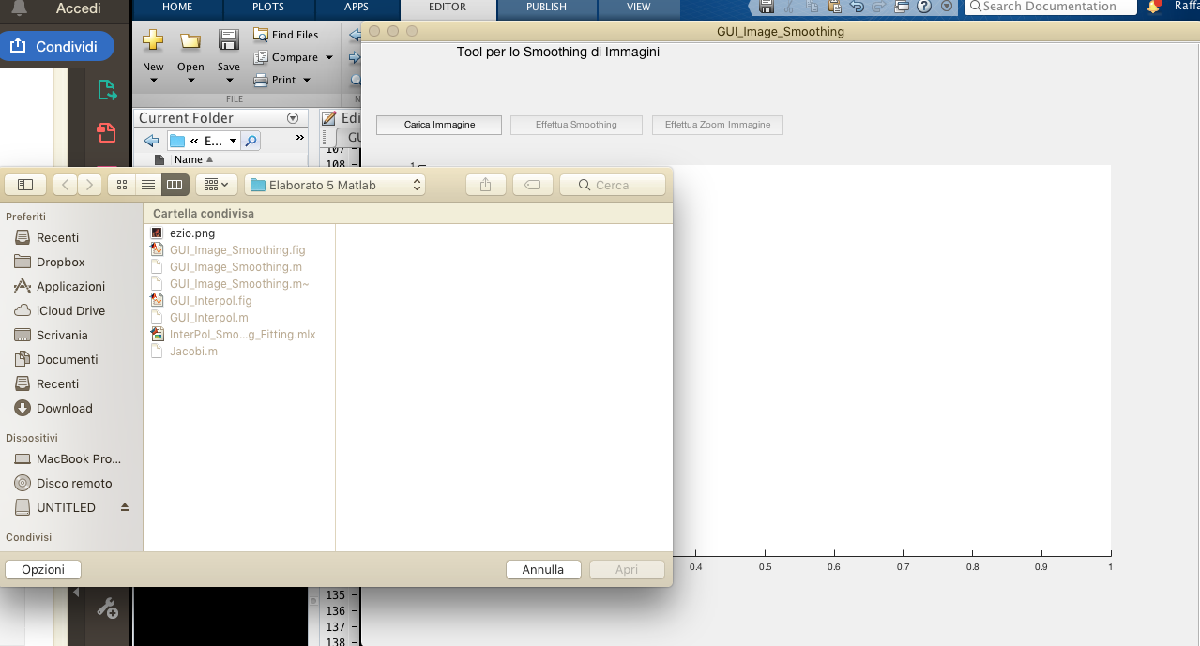

- Click su "Effettua Smoothing"

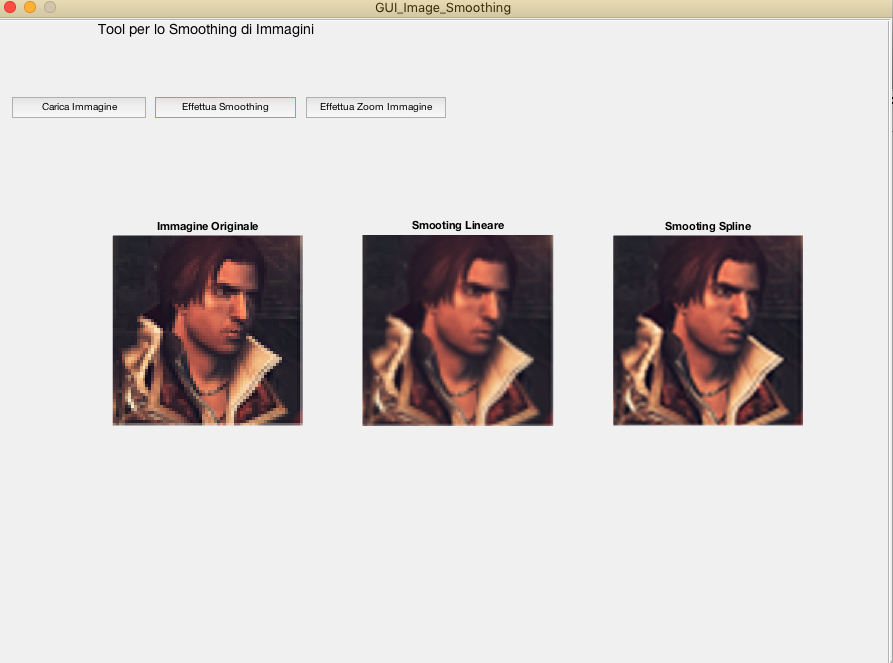

- Click su "Effettua Zoom Immagine"

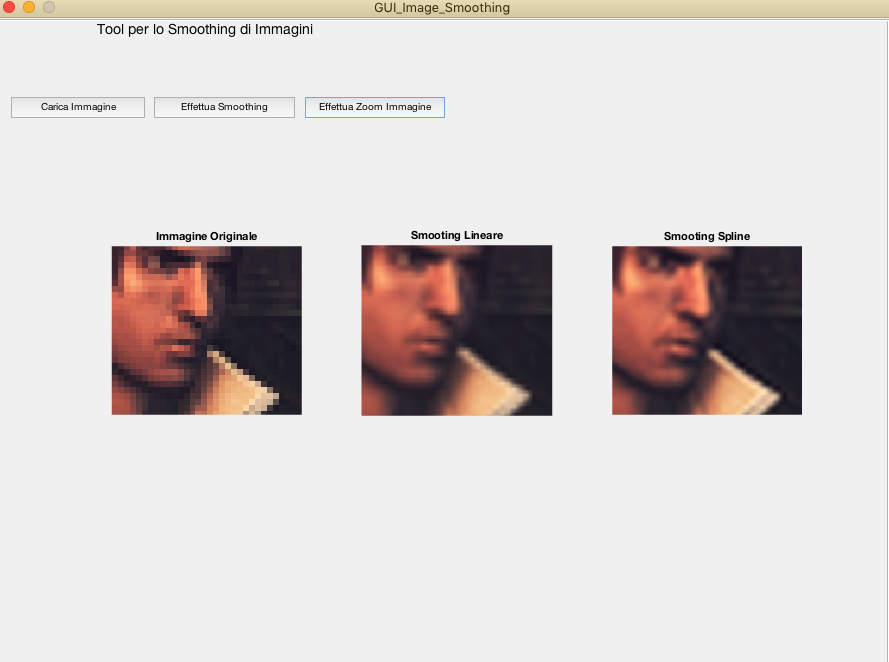

## Riferimenti

- *Econometrics Toolbox, *[*https://it.mathworks.com/help/econ/data-sets-and-examples.html*](https://it.mathworks.com/help/econ/data-sets-and-examples.html)

- *Wikipedia - Paraboloide Ellittico, *[*Wikipedia : Paraboloide Ellittico*](https://it.wikipedia.org/wiki/Paraboloide)

- *Soccer Statistics, WhoScored, *[*https://www.whoscored.com/Statistics*](https://www.whoscored.com/Statistics)

- *MATLAB Gui, *[*https://it.mathworks.com/discovery/matlab-gui.html*](https://it.mathworks.com/discovery/matlab-gui.html)

- [*Docenti.unina.it D'alessio Alessandra*](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

## Autori

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***